CODE ADDITIONS 

7/8/2026; 7:53 pm (Isaac)

- Implemented an image processing algorithm that (mostly) works for Tube images. It needs testing.

7/9/2026; 4:34 pm (Ryan)

- Updated Dataset organization so that each subfolders organization matches. Changed to imageDatastore and added class labels and pass/fail classification for each image.

7/11/2026; 4:14 pm (Ryan)

- Added corner removal to improve output decision reliability. Added comments to better explain which image is which when selected from the range (Tubes only).

7/12/2026; 10:52 am (Ryan)

- Added labels to ROI that correspond to each table entry for easier analysis of performance. Adjusted minimum eccentricity to improve detection of short tubes as anomalous.

7/16/2026; 4:06 pm (Ryan)

- Adjusted the singleimageinspectionfunction to run without displaying output, allowing for faster results to be gathered for batch processing. Basic batch processing implemented, will need further improvements. Corrected some program errors. 

7/19/2026; 11:04 am (Ryan)

- Added yield and defect rates and also a pass/fail confusion matrix. Separated batch inspection into its own function and removed unnecessary code.

7/19/2026: 11:12 PM (Isaac)

- Added trainModel checkbox to allow for easy triggering of AI classifier training when we want it

- Separated Color and Shape detection in singleImageInspectionFunction.mlx into their own separate functions in their own respective scripts to improve code readability.

- Removed inclusion of dispOutput from singleImageInspectionFunction.mlx and newly-separated function scripts (no longer needed)

- Modified reportData structure to include images (original/masked/annotated images) and statistics (num Normal/Color Anomality/Shape Anomaly tubes) in separate "images" and "metrics" fields respectively

Choose Data Subset of Interest, Adjust Parameters

dataSubset = "tubes";
displayOrginalImage =false;
displayClassicalInspectionData =false;
useAIClassifier =true;
trainModel = true

trainModel = logical
   1



performBatchTesting =true;

Current working algorithm

Detected 5 classes to learn.
    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:06       0.0001                            1.6207                                    15.217
            1        1       00:00:06       0.0001          3.2687                                  6.25                      
           10        1       00:00:30       0.0001          1.1538           0.93982                37.5                63.043
           20        2       00:00:49       0.0001         0.86859           0.24772               68.75                93.478
           30        3       00:01:09       0.0001         0.22602           0.18315                87.5                95.652
           40        4       00:01:28       0.0001         0.31744           0.227

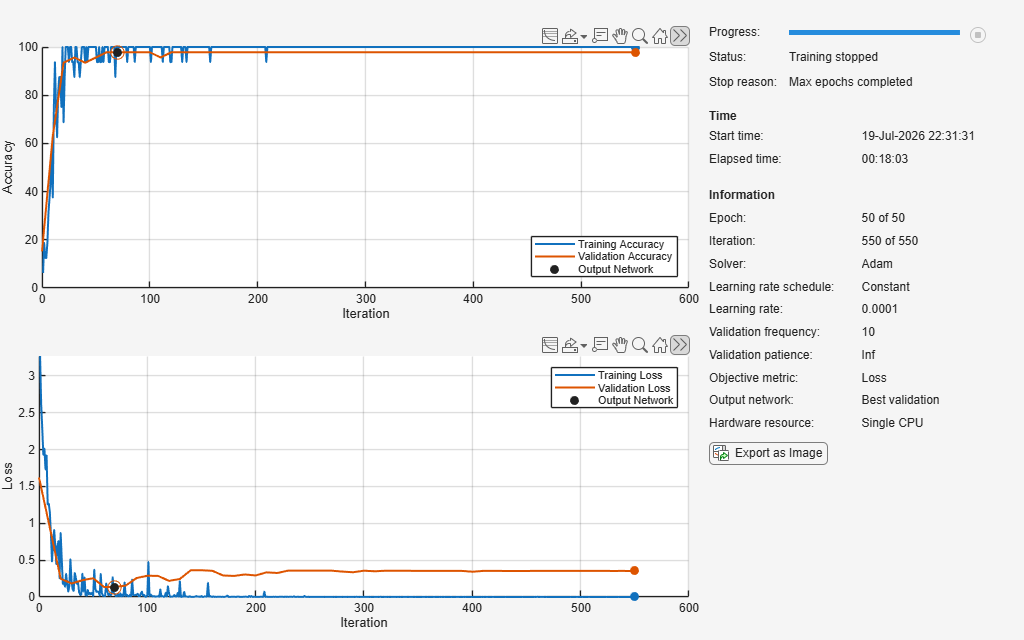

% Obtain the file location of the dataset. 
% ***IMPORTANT***
% This file location stored is a RELATIVE path!!!
% For this script to run, your active path must be set to where
% the MPDD dataset is stored on your local system.
%
% To change your active path, click the "Set Path" option under the
% "Environment" sub tab within the MATLAB application. 
fileLoc = sprintf("MPDD/%s", dataSubset);


% Creates an image Datastore to store all images of specified subset type.
% The image Datastore is setup to specifically look for images with certain file
% extensions that are common for images (i.e. jpg, png, etc.)
ds = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

% Filter 'ground truth'/masks that are only used for model verification
excludeMask = contains(ds.Files, "gt*" | "mask");
ds = subset(ds, ~excludeMask);

% Obtain the number of files within the selected sub directory
numFiles = numel(ds.Files);

% ***Image processing begins here***
%
% Load the image of interest from the datastore object
% Color mismatch    01 - 008, + 21
% Defective Length  09 - 021
% Malformed Metal   54 - 103, + 8
% Good              22 - 053, + 104 - 225
% NOTE: changes made to folders have made these ranges unreliable
imgNum = 8;
img = readimage(ds, imgNum);

% Labels image and (Optionally) Displays class & image info
% imgClass <-- Official label of the image
% imgPF <-- Whether or not the part would pass or fail
imgClass =  ds.Labels(imgNum); 

if displayOrginalImage
    numObsPerClass = countEachLabel(ds)
    imgInfo = sprintf("Image class: %s", imgClass);

    disp("Number of Files: " + numFiles);
    imshow(img);
    title(imgInfo);
end

% Train the model if trainModel is enabled HIGH and 
% tubeClassifierNet.mat does not exist in current directory
if trainModel & ~isfile("tubeClassifierNet.mat")
    training(ds);
end


% Inspect the image and print out a report
pass = singleImageInspectionFunction(img, displayClassicalInspectionData, useAIClassifier);
disp(pass);

      Decision: "FAIL"
    Confidence: 98.6538
       AIClass: color_mismatch
       metrics: [1×1 struct]
        images: [1×1 struct]
        iamges: [1×1 struct]



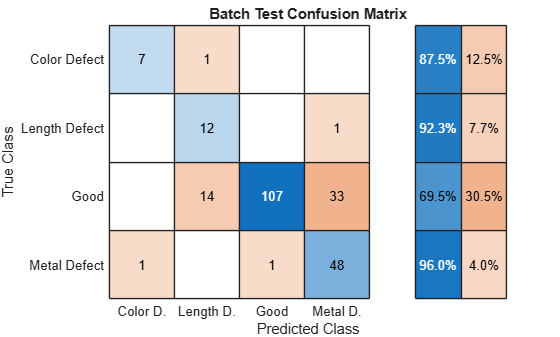

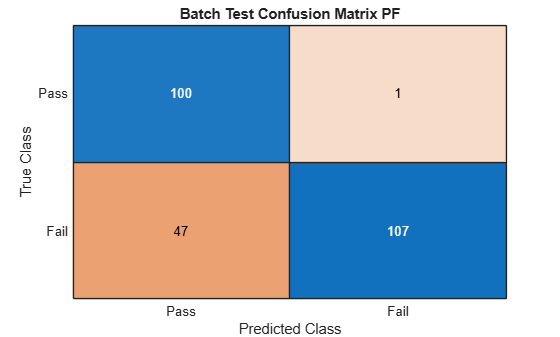

Actual Yield: 68.4%
Predicted Yield 48.0%

Defect Rate: 31.6%
Escaped Defect Rate 1.0%





% Batch image classifier
if performBatchTesting
    runBatchInspection(ds);
end